## Parameters

clear;
N_observation = 10;
N_sample = 8192; 
n_subcarrier = 256;
symbols_per_frame = 2;
T_symbol = 1e-4;
pri = T_symbol*symbols_per_frame;
freq_carrier = 3e9;
freq_IF = 2e7;
freq_sampling = N_sample / T_symbol;
lambda = 3e8 / freq_carrier;
prf = 1 / pri;
range_per_sampling_period = 3e8 * (1/freq_sampling) / 2;
t2 = (linspace(0, T_symbol, N_sample))';  % symbol time axis

range_target_ref = 5000; % range target in meter for testing
vel_target_ref = 30; % velocity target in m/s for testing

## Wave Generator

%golay coding
golay_reg = golay(n_subcarrier);
golay_symbol_index = 1;
golay_code_value = golay_reg(golay_symbol_index, :);

%phase shifting
% alpha = deg2rad(90);
% deltat = -alpha ./ (2*pi*f);
% phase_shift = exp(1j * 2 * pi * f .* deltat);
% signal = golay_code_value .* phase_shift;

%ifft
iq_signal = ifft(golay_code_value, N_sample)';

% IF frequency 
carrier = exp(-1i*2*pi*(freq_IF)*t2);
iq_signal = iq_signal .* carrier;

%IQ modulator with zero padding
tx_signal = (real(iq_signal) + imag(iq_signal));
zero_padded_signal = [tx_signal; zeros((N_sample*(symbols_per_frame-1)), 1)];

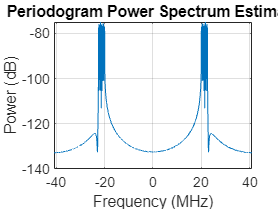

% Tx Signal Spectrum
periodogram(tx_signal,[],N_sample,freq_sampling,'power','centered')

## Antenna & Channel Initialization

target = phased.RadarTarget('Model','Nonfluctuating',...
    'MeanRCS',1,'OperatingFrequency',freq_carrier);
targetpos = phased.Platform('InitialPosition',[range_target_ref; 0; 0],...
    'Velocity',[vel_target_ref; 0; 0]);
antenna = phased.IsotropicAntennaElement(...
    'FrequencyRange',[5e8 5e9]);
transmitter = phased.Transmitter('PeakPower',5e3,'Gain',34,...
'InUseOutputPort',true);
transpos = phased.Platform('InitialPosition',[0;0;0],...
    'Velocity',[0;0;0]);
radiator = phased.Radiator('OperatingFrequency',freq_carrier,'Sensor',antenna);
collector = phased.Collector('OperatingFrequency',freq_carrier,'Sensor',antenna);
channel = phased.FreeSpace('SampleRate',freq_sampling,...
    'OperatingFrequency',freq_carrier,'TwoWayPropagation',false);
receiver = phased.ReceiverPreamp('Gain',100,'LossFactor',0,...
    'SampleRate',freq_sampling,'NoiseFigure',5,...
    'EnableInputPort',false,'SeedSource','Property','Seed',1e3);

## Antenna and Channel Modelling

sig = zero_padded_signal; 
transpos = transpos.InitialPosition; 
rxsig = zeros(length(sig),N_observation);

for i = 1:N_observation
    % update target position
    [tgtpos,tgtvel] = targetpos(pri); 
    % update target range and angle
    [tgtrng,tgtang] = rangeangle(tgtpos,transpos); 
    % transmit waveform
    [txsig,txstatus] = transmitter(sig); 
    % radiate waveform toward target
    txsig1 = radiator(txsig,tgtang);
    % propagate waveform to target
    txsig2 = channel(txsig1,transpos,tgtpos,[0;0;0],tgtvel); 
    % reflect the signal
    txsig3 = target(txsig2); 
    % propagate waveform from the target to the transmiter
    txsig4 = channel(txsig3,tgtpos,transpos,tgtvel,[0;0;0]);
    % collect signal
    txsig5 = collector(txsig4,tgtang); 
    % receive the signal
    rxsig(:,i) = receiver(txsig5); 
end

% received signal during N_observation
rx_signal = real(rxsig) + imag(rxsig);

rx_signal_1 = rx_signal(:,1);
rx_signal_2 = rx_signal(:,2);
rx_signal_3 = rx_signal(:,3);
rx_signal_4 = rx_signal(:,4);
rx_signal_5 = rx_signal(:,5);
rx_signal_6 = rx_signal(:,6);
rx_signal_7 = rx_signal(:,7);
rx_signal_8 = rx_signal(:,8);
rx_signal_9 = rx_signal(:,9);
rx_signal_10 = rx_signal(:,10);

## Correlation and Range Processing

[c,lags] = xcorr(rx_signal_1, sig);

% getting the right-side correlation spectrum
size_lags =  size(lags, 2);
lags_abs = lags(1, round(size_lags/2):size_lags);
c_abs = (c(round(size_lags/2):size_lags, 1));

% getting the lag index, time lag, and range
lag_of_max_corr = lags_abs(c_abs == max(c_abs))

lag_of_max_corr = 2738

lag_delay_time = (1/freq_sampling) * lag_of_max_corr;
range = 3e8 * lag_delay_time / 2

range = 5.0134e+03

range_target_ref

range_target_ref = 5000

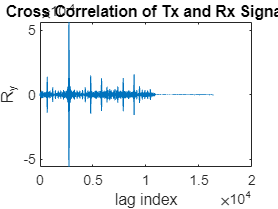

% plotting the correlation and lag index
plot(c_abs);
xlabel('lag index');
ylabel('R_x_y');
title('Cross Correlation of Tx and Rx Signal');

## Doppler and Velocity Processing

% getting the n-th sample signals from each observation where n is the lag
% index
slow_time_samples = rx_signal(lag_of_max_corr,:).';

% fft to get the doppler freq and velocity
n = 32;
y = fft(slow_time_samples, n);
f = (0:n-1)*(prf/n); 
power = abs(y).^2;  

[Y_fft,I_fft] = max(power);
doppler_freq = f(I_fft)

doppler_freq = 625

vel = dop2speed(f(I_fft)/2,lambda)

vel = 31.2500

vel_target_ref

vel_target_ref = 30

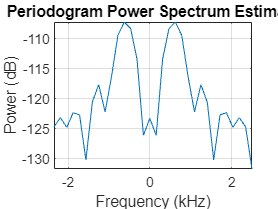

% plotting the doppler frequency spectrum
periodogram(rx_signal(lag_of_max_corr,:).',[],32,prf,'power','centered')